## define the system and its closed loop

s = 27.56j;
K = abs(s^3 + 170*s^2 + 6000*s)

K = 1.9373e+05

numerator = K;
denominator = conv([1 0], conv([1 50], [1 120]));  % (s)(s+50)(s+120)
L = tf(numerator, denominator)  % open-loop transfer function

L =
 
         1.937e05
  ----------------------
  s^3 + 170 s^2 + 6000 s
 
Continuous-time transfer function.
Model Properties



T = feedback(L, 1)

T =
 
              1.937e05
  ---------------------------------
  s^3 + 170 s^2 + 6000 s + 1.937e05
 
Continuous-time transfer function.
Model Properties


## show open loop bode

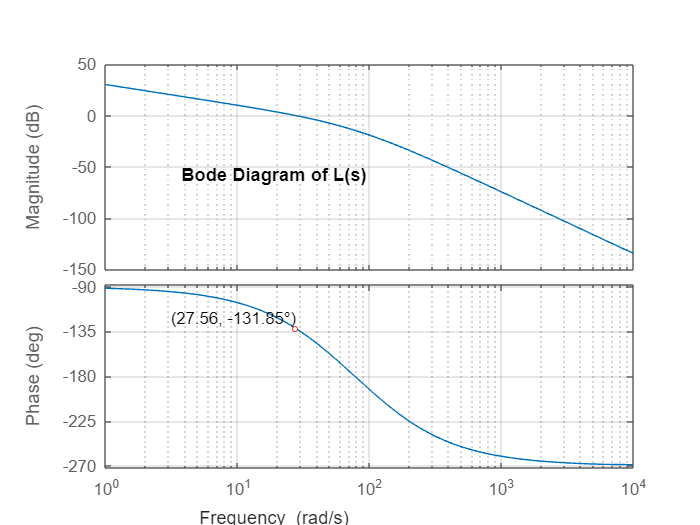

bode(L)
grid on;
title('Bode Diagram of L(s)');

hold on

% Souřadnice markeru
x_val = 27.56; % frekvence v rad/s, nastav si podle potřeby
y_val = -131.8523; % fáze v °

% Přidání markeru
plot(x_val, y_val, 'ro', 'MarkerSize', 3, 'MarkerFaceColor', 'auto');

% Přidání popisku
text(x_val, y_val, sprintf('(%.2f, %.2f°)', x_val, y_val), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

hold off

print('graphs/Bode_L(s)','-depsc');

## extract poles from closed loop

p = pole(T)

p = 1.0e+02 *

  -1.3643 + 0.0000i
  -0.1679 + 0.3374i
  -0.1679 - 0.3374i


## show step response of closed loop

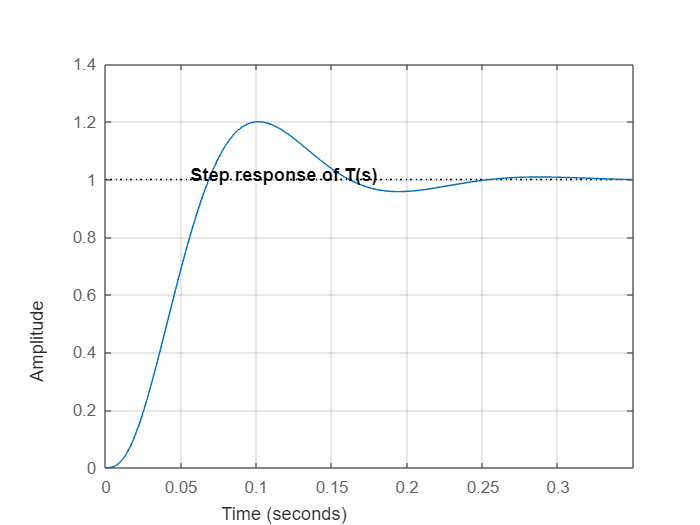

step(T)
grid("on");
title('Step response of T(s)')
print('graphs/Step_response_T(s)','-depsc');